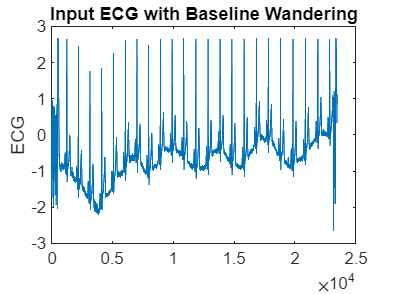

clc
clear all
close all

%Preprocessing

pec = load('pec1.dat');

%pec(:,1) - PCG, pec(:,2) - ECG, pec(:,3) - PPG 
%HPF to remove Baseline wandering in ECG
Z1=1; P1=0.995;
Nu=[1 -Z1]; De=[1 -P1];
hd = dfilt.df2(Nu,De); %Digital Filter Direct Form II

ecg = filter(hd,pec(:,2));

figure(1)
plot(pec(:,2))
title('Input ECG with Baseline Wandering')
ylabel('ECG')

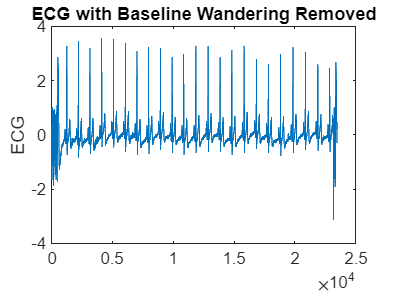

figure(2)
plot(ecg)
ylabel('ECG')
title('ECG with Baseline Wandering Removed')

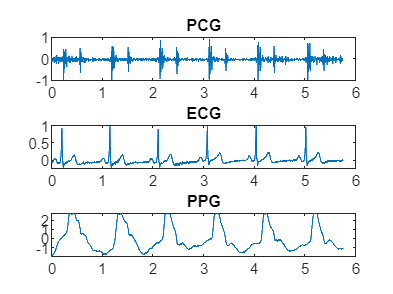


%Plot few cycles from the inputs (PCG, ECG & PPG)
st = 1050;
ed = 6800;
PCG = pec(st:ed,1);
ppg = pec(st:ed,3);
ecg = ecg(st:ed);

ecg = ecg/max(abs(ecg));
PCG = PCG/max(abs(PCG));

fs=1000;
slen = length(ecg);
t = [1:slen]/fs;

figure(3)
title('Input Data: PCG, ECG & PPG')
subplot(3,1,1);
plot(t,PCG);
title('PCG')
subplot(3,1,2);
plot(t,ecg);
title('ECG')
subplot(3,1,3);
plot(t,ppg);
title('PPG')

## QRS Detection in ECG

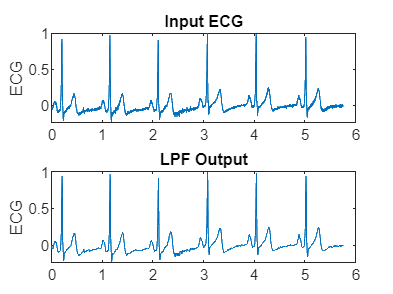


%Bandpass filtering of ECG
%First LPF
Nu = [1 0 0 0 0 0 -2 0 0 0 0 0 1];
De = [1 -2 1]*32;
hd1 = dfilt.df2(Nu,De); %Digital Filter DF II

ecg_out1 = filter(hd1,ecg);

ecg_out1 = ecg_out1-mean(ecg_out1);
ecg_out1 = ecg_out1/max(abs(ecg_out1));

figure(4)
subplot(2,1,1);
plot(t,ecg);
title('Input ECG')
ylabel('ECG')
subplot(2,1,2);
plot(t,ecg_out1)
title('LPF Output')
ylabel('ECG')

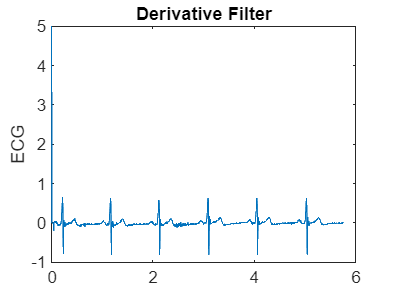


%Next HPF
Num = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 32 -32 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
Den = [1 -1]*32;
hd2 = dfilt.df2(Num,Den);
ecg_out2 = filter(hd2, ecg_out1);
ecg_out2 = [ecg_out2(1:40)*0.25; ecg_out2(41:end)];

ecg_out2 = ecg_out2 - mean(ecg_out2);
ecg_out2 = ecg_out2/max(abs(ecg_out2));


%Derivative Filter
Nu = [2 1 0 -1 -2];
De = [1]*8;
hd3 = dfilt.df2 (Nu, De);

ecg_out3=filter(hd3,ecg_out2);

ecg_out3 = ecg_out3-mean(ecg_out3);
ecg_out3 = ecg_out3/max(abs(ecg_out3)).*5;

figure(5)
plot(t,ecg_out3);
title('Derivative Filter')
ylabel('ECG')

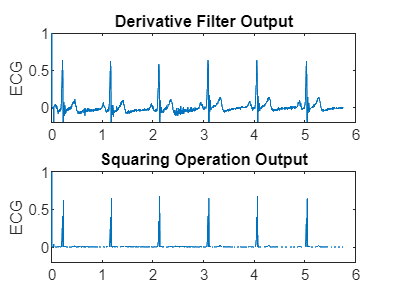


%% Squaring

ecg_out4 = ecg_out3 .^2;
ecg_out4 = ecg_out4/max(abs(ecg_out4)).*25;

figure(6)
subplot(2,1,1);
plot(t,ecg_out3);
ylim([-0.2 1])
title('Derivative Filter Output')
ylabel('ECG')
subplot(2,1,2);
plot(t,ecg_out4);
ylim([-0.2 1])
title('Squaring Operation Output')
ylabel('ECG')

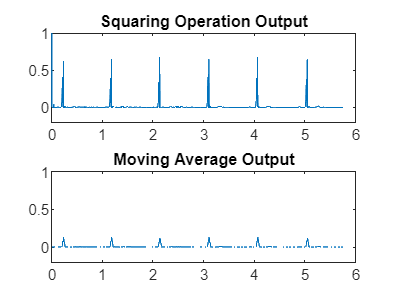



%% Integration Operator
% Zero-padding
ecg_out4pad = [zeros(1,29) ecg_out4' zeros(1,29)];
for i=30:length(ecg_out4pad)-29
    ecg5(i-29)=sum(ecg_out4pad(i-29:i))/30;
end
ecg5 = ecg5';
ecg5 = ecg5/max(abs(ecg5));
ecg5(1:50) = 0;

figure(7)
subplot(2,1,1);
plot(t,ecg_out4);
ylim([-0.2 1])
title('Squaring Operation Output')
subplot(2,1,2);
plot(t,ecg5);
ylim([-0.2 1])
title('Moving Average Output')

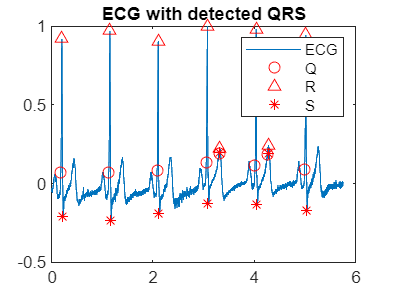



%QRS Complex Detection
%Thresholding
TH = mean(ecg5);
W = (ecg5>TH);
% Finding location of 0 to l transition
x = find(diff([0 W']) == 1);
% Finding location of 1 to 0 transition
y = find(diff([W' 0]) == -1);
%To cancel the delay caused by LPF and HPF
x = x-(6+16);  %6 from LP, 16 from HP
y = y-(6+16);

for i=1:length(x)-1
% R Locations
[R_value(i),R_loc(i)] = max(ecg(x(i):y(i)));
R_loc(i) = R_loc(i)-1+x(i);% add offset
% Q Locations
[Q_value(i), Q_loc(i)] = min(ecg(x(i):R_loc(i)));
Q_loc(i) = Q_loc(i)-1+x(i);  % add offset
Q_value(i) = ecg(Q_loc(i));
% S Locations
[S_value(i), S_loc(i)] = min(ecg(R_loc(i):y(i)));
S_loc(i) = S_loc(i)-1+x(i);  % add offset

end
 
figure(8)
plot(t,ecg, t(Q_loc), Q_value,'ro', t(R_loc), R_value, 'r^', t(S_loc), S_value, 'r*');
title('ECG with detected QRS'); 
legend('ECG','Q', 'R','S');

## Dicrotic Notch Detection in PPG

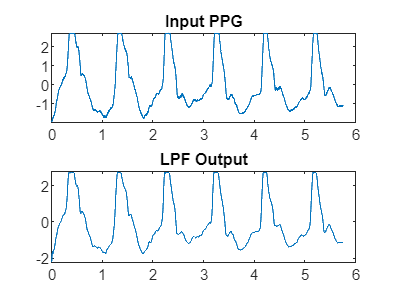

% LPF with cut off frequency 40Hz
Fs = 1000;  % Sampling Frequency
N = 8; %Order
Fc = 40; % Cut-off Frequency
h = fdesign.lowpass('N,F3dB', N, Fc, Fs);
Hd_40 = design(h,'butter');
Crot1 = filter(Hd_40, ppg); %Crot contains Carotid pulse signal
Crot1 = [Crot1(34:end); Crot1(slen-32:slen)]; %To remove some unwanted samples


figure(9)
subplot(2,1,1)
plot(t,ppg)
title('Input PPG')
subplot(2,1,2)
plot(t,Crot1)
title('LPF Output')

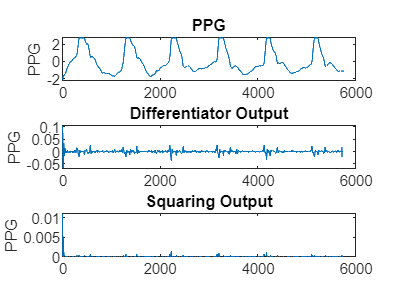



% Adding few samples in front (reflection padding) for differentiation
C = [Crot1(2) Crot1(1) Crot1' Crot1(slen) Crot1(slen-1)];

% Lehner Rangayyan differentiator
for n = 3:slen+2
P(n-2) = 2 * C(n-2) - C(n-1) - 2 * C(n) - C(n+1) + 2 * C(n+2);
end
Ps=P.^2; % Squared

figure(10)
subplot(3,1,1)
plot(C)
title('PPG')
ylabel('PPG')
subplot(3,1,2)
plot(P)
title('Differentiator Output')
ylabel('PPG')
subplot(3,1,3)
plot(Ps)
title('Squaring Output')
ylabel('PPG')

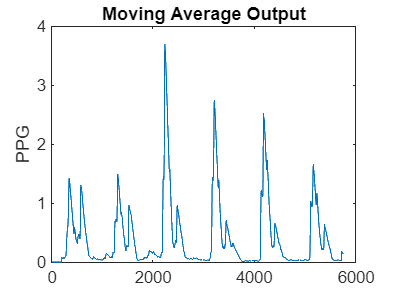



%Moving Average
M = 164;  % Window size

Ps = [wrev(Ps(1,1:M)), Ps, wrev(Ps(1,slen-M+1:slen))];
%"wrev" function needs WWavelet Toolbox, gives reverse of the signal
s1 = zeros(1,slen);
% Lehner Rangayyan MA Filter
for i = M:slen+M-1
    for j=1:M
        s1(i-M+1) = s1(i-M+1) + (Ps(i-j+1)*(M-j+1));
    end
end
s1(1:200) = 0;%Initial samples

figure(11)
plot(s1)
title('Moving Average Output')
ylabel('PPG')


% Finding peaks in MA output
[pks, locs] = findpeaks(s1);  % Peak
%values and locations
[pks1, locs1] = findpeaks(pks);
s3 = zeros(1,slen);
s3(locs(locs1)) = pks1;
s4 = (s3>0.5);  %Prominent Peaks
[~,a2] = find(s4==1) ;  %Locations
k=1;

for i=1:length(a2)-1
    val = a2(i+1) - a2(i);
       if val > 180 && val <340
       Dpks(k) = a2(i+1);
       k = k + 1;
       end
end

% To find D-notch within 20ms of second peak
for i = 1:length(Dpks)
    for j = Dpks(i):-1:Dpks(i)-50
        if (Crot1(j+7) > Crot1(j)) && (Crot1(j-7) > Crot1(j))
        a3(i) = Dpks(i)-j; break;
        end
    end
end
Dpks1 = Dpks - round(mean(a3));


## Plotting S1 & S2 of PPG using ECG & PPG

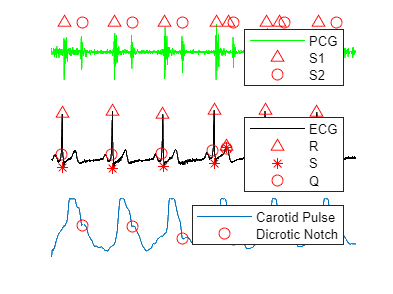

%Plotting QRS & Dicrotic Notch

v = ones(1,length(Dpks1)); % To show S1 and S2 in PCG
v2 = ones(1,length(R_loc));

figure(12); 
subplot(3,1,1);
% Plotting PCG with S1 and S2

plot(t, PCG , 'g', t(R_loc+35), v2, 'r^', t(Dpks1), v, 'ro');
legend('PCG','S1','S2'); axis tight; axis off;

% Plotting ECG with detected QRS
subplot(3,1,2)
plot(t,ecg/max(ecg), 'k', t(R_loc), R_value, 'r^', t(S_loc), S_value, 'r*', t(Q_loc), Q_value, 'ro');
legend('ECG','R','S','Q'); axis tight; axis off;

% Plotting Carotid Pulse (PPG) signal with Dicrotic notch
subplot(3,1,3);
plot(t, Crot1, t(Dpks1), Crot1(Dpks1), 'ro');
legend('Carotid Pulse','Dicrotic Notch');
axis tight; axis off;
ylabel('Carotid Pulse');